lid = LIDAR('COM11')

lid.scan(400);

fprintf(lid.lidar, 'QT');
fclose(lid.lidar);
clear lidar;
warning('on');
disp("the lidar has successfully been terminated")

clear
clc
%camList = webcamlist()
cam = Camera();

cam.show()


[id,loc,pose] = cam.poses()

cam.disp_tags();

imshow(ans)

while true
    
    imshow(cam.disp_tags())
    pause(1)
end

[id, loc, poses] = cam.poses()

neo = NEO_M8U_USB("COM13") 

basic_data = neo.getBasic() 

  [robotArduino]= SETUPARDUINO('COM6')   

robotArduino =   arduino with properties:

                  Port: 'COM6'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


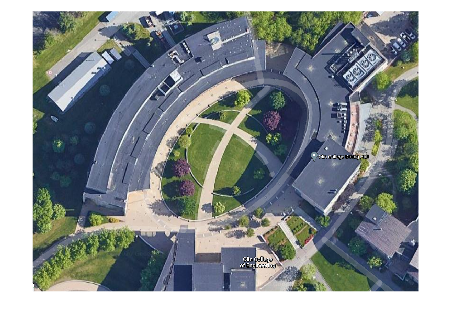

img = imread('OlinOvalColor.PNG'); 
imshow(img);

grayimage = im2gray(img);                           % convert to grayscale
imshow(grayimage)
bwimage = grayimage < 0.5; 
MapOfOval = binaryOccupancyMap(img, 10);        % convert to a binary occupancy map in meters

Error using binaryOccupancyMap
Expected input number 1, P, to be two-dimensional.

Error in matlabshared.autonomous.internal.MapInterface.validateMatrixInput (line 745)
                validateattributes(P, {'numeric','logical'}, ...

Error in 

show(MapOfOval);  

        % semi-colon left off to confirm Nano is connected

clear drive;
drive = servo(robotArduino, 'D3', 'MinPulseDuration', 1500*10^-6, 'MaxPulseDuration', 1550*10^-6);
writePosition(drive, 0.5);      % always start servo-command at 0.5

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end